# PRACTICA 4 

## VENTANAS

Dada la señal x[n]=1,5 cos(0,2⇡n)+0,1 cos(0,35⇡n)+0,7 cos(0,6⇡n) 

Representa su DTFT entre 0 y ⇡ para N = 60 Aplica los diferentes tipos de ventanas (Bartlett, Hanning, Hamming y Blackman) y representa en tiempo y en frecuencia la se˜nal enventanada compar´andola con la se˜nal original 

N=60;
n=linspace(0,N-1,N);
omega=linspace(0,pi,N);
x=1.5.*cos(0.2*pi.*n)+0.1.*cos(0.35*pi.*n)+0.7.*cos(0.6*pi.*n)

x =     2.3000    1.0426   -0.1616    0.0040   -1.0281   -2.1293   -0.9021    0.1184   -0.1837    0.9081    2.2000    1.0863   -0.0219    0.0871   -1.0923   -2.2707   -0.9663    0.2016   -0.0440    0.9518    2.1000    0.9518   -0.0440    0.2016   -0.9663   -2.2707   -1.0923    0.0871   -0.0219    1.0863    2.2000    0.9081   -0.1837    0.1184   -0.9021   -2.1293   -1.0281    0.0040   -0.1616    1.0426    2.3000    1.0426   -0.1616    0.0040   -1.0281   -2.1293   -0.9021    0.1184   -0.1837    0.9081


X=DTFT(x,n,omega)

X =    0.1000 + 0.0000i   2.2102 + 0.3934i   0.0582 + 0.1338i   2.2975 + 1.2485i  -0.0832 + 0.2845i   2.5086 + 2.3559i  -0.3914 + 0.4809i   2.9645 + 4.1311i  -1.0967 + 0.8035i   4.1549 + 8.1084i  -3.4793 + 1.6734i  11.5112 +31.0257i  42.5500 -13.1774i  -5.7712 -21.9018i   4.9541 - 0.8353i  -1.5007 - 8.4746i   3.2144 - 0.0923i  -0.5801 - 5.2363i   2.7026 + 0.4163i  -0.3982 - 3.5814i   3.3245 + 2.1998i   2.7805 - 4.4628i   1.1798 - 0.7370i   0.9568 - 2.5897i   1.3541 + 0.0492i   0.9835 - 1.9978i   1.2532 + 0.4193i   1.1312 - 1.5300i   1.0609 + 0.7852i   1.3790 - 1.0771i   0.7324 + 1.2992i   1.8380 - 0.5210i   0.0376 + 2.3023i   3.0342 + 0.5379i  -2.5998 + 5.9730i  16.0672 +10.1736i  12.2767 -14.4643i  -3.4619 - 3.8653i   4.2569 - 3.3884i  -1.2874 - 2.1482i   3.2089 - 1.9075i  -0.6657 - 1.5687i   2.7967 - 1.3004i  -0.3726 - 1.2350i   2.5781 - 0.9580i  -0.2039 - 0.9970i   2.4446 - 0.7304i  -0.0963 - 0.8071i   2.3567 - 0.5625i  -0.0238 - 0.6450i


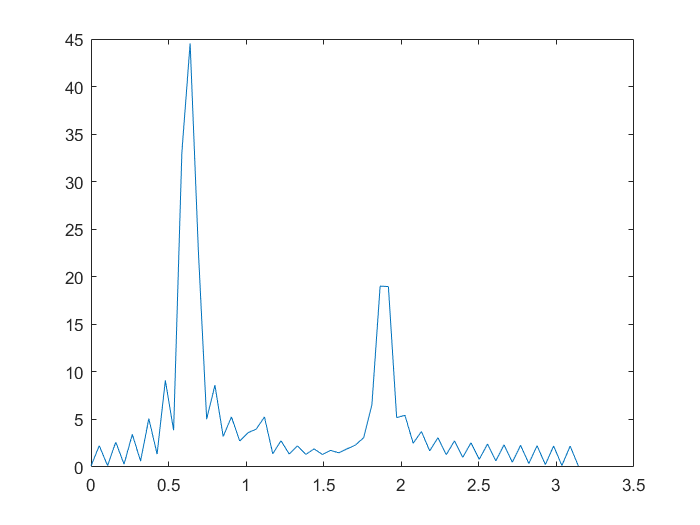

plot(omega,abs(X))

Señal de prueba suma de cosenos:

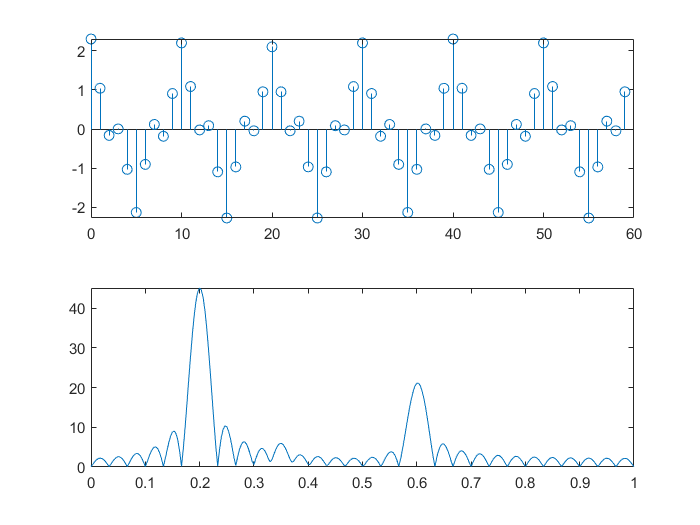

f1 = 0.2;
f2 = 0.35;
f3 = 0.6;
N  = 60;
n  = linspace(0,N-1,N);
x  = 1.5*cos(f1*pi*n)+0.1*cos(f2*pi*n)+0.7*cos(f3*pi*n);
w  = linspace(0,pi,301);
X  = DTFT(x,n,w);
subplot(211);stem(n,x);subplot(212);plot(w/pi,abs(X))

Aplica los diferentes tipos de ventanas (Bartlett, Hanning, Hamming y Blackman) y representa en tiempo y en frecuencia la se˜nal enventanada compar´andola con la se˜nal original 

w_Bartlett=triang(N)

w_Bartlett =     0.0167
    0.0500
    0.0833
    0.1167
    0.1500
    0.1833
    0.2167
    0.2500
    0.2833
    0.3167


xb=x.*w_Bartlett';
%Debo hacer la traspuesta del filtro ya que el "." hace que vaya multiplicando 1 por 1, obteniendo una matriz 60x1, y las demás son 1x60
%asi que debo trasponerlo 
%para trasponer utilizo ' , si tuviese complejo imaginaria seria .'
XB=DTFT(xb,n,omega);
plot(omega,abs(XB))
title('Filtro Barlett en frecuencia')%en frecuencia siempre me quedo con la parte absoluta, abs
%%
plot(omega, real(xb), omega, real(x)) %en tiempo uso real
title('Filtro Barlett en tiempo')

Ventana Triangular o Bartlett:

x1 = x.*triang(N)';
X1  = DTFT(x1,n,w);
figure;subplot(211);plot(n,x,n,x1);subplot(212);plot(w/pi,abs(X1))

Ventana Hanning:

x2 = x.*hann(N)';
X2  = DTFT(x2,n,w);
figure;subplot(211);plot(n,x,n,x2);subplot(212);plot(w/pi,abs(X2))

Ventana Hamming:

x3 = x.*hamming(N)';
X3  = DTFT(x3,n,w);
figure;subplot(211);plot(n,x,n,x3);subplot(212);plot(w/pi,abs(X3))

Ventana Blackman:

x4 = x.*blackman(N)';
X4  = DTFT(x4,n,w);
figure;subplot(211);plot(n,x,n,x4);subplot(212);plot(w/pi,abs(X4))

Comparación entre las 4 ventanas:

subplot(111);plot(w/pi,abs (X),'k:',w/pi,abs(X1),'b',w/pi,abs(X2),'m',w/pi,abs(X3),'g',w/pi,abs(X4),'r')

w_Hanning=hann(N);
xhan=x.*w_Hanning';
XHAN=DTFT(xhan,n,omega);
plot(omega,abs(XHAN))
title('Filtro Hanning en frecuencia')
%
plot(omega, real(xhan), omega, real(x)) 
title('Filtro Hanning en tiempo')


w_Hammimg=hamming(N);
xham=x.*w_Hammimg';
XHAM=DTFT(xham,n,omega);
plot(omega,abs(XHAM))
title('Filtro Hamming en frecuencia')
%
plot(omega, real(xham), omega, real(x)) %en tiempo uso real
title('Filtro Hammimg en tiempo')

w_Blackman=blackman(N);
xblack=x.*w_Blackman';
XBLACK=DTFT(xblack,n,omega);
plot(omega,abs(XBLACK))
title('Filtro Blackman en frecuencia')
%
plot(omega, real(xblack), omega, real(x)) %en tiempo uso real
title('Filtro Blackman en tiempo')

## FILTROS FIR

Dada la se˜nal x[n]=1,5 cos(0,2⇡n)+0,1 cos(0,35⇡n)+0,7 cos(0,6⇡n) 

N=60;
n=linspace(0,N-1,N);
omega=linspace(0,pi,N);
x=1.5.*cos(0.2*pi.*n)+0.1.*cos(0.35*pi.*n)+0.7.*cos(0.6*pi.*n);
X=DTFT(x,n,omega)

**Filtradla paso bajo** para que sólo quede la señal de frecuencia 0,2pi usando un filtro basado en la DFT

Para ayudar se proporciona la función H = pasobajo(kf , wp, ws) en la que se introducen como valores de entrada la frecuencia normalizada (w/pi), el l´ımite de la banda de paso wp y de la banda eliminada ws , las dos en valores normalizados 

Representadlo en tiempo (comparando con la señal que debería dar) y frecuencia (comparando la DTFT con la de la señal original)

Nh=40; %supongo este valor para obtener unas divisiones de 0,05 de manera que un valor me coincida en 0.2 y otro en 0.35
k=linspace(0,Nh-1,Nh) 
kf=k*2/Nh; 
H=pasobajo(kf,0.2,0.3); %fijo que hasta 0.2pi/pi el filttro valga 1, y a partir de 0.3pi/pi valga 0 y asi quede fuera 0.35pi
stem(kf,abs(H))
title('Filtro paso bajo')
h=ifft(H) %compruebo que Nh son 40
next=-Nh+1:N-1; %extiendo xn hasta 99 valores
xn=1.5.*cos(0.2*pi.*next)+0.1.*cos(0.35*pi.*next)+0.7.*cos(0.6*pi.*next);
nn=N+Nh-1
y_provisional=ifft(fft(xn).*fft(h,nn))
y=y_provisional(40:end) %quiero deshacerme de los 39 primeros valores, como empiezo en 1, cojo como primero el 40
plot(n,real(y),n,real(x))
title('Filtro paso bajo en tiempo')
%
Y=DTFT(y,n,omega); %se aprecia mejor en frecuencia
plot(omega,abs(Y),omega,abs(X)) 
title('Filtro paso bajo en frecuencia')

### Filtro FIR

Señal de prueba suma de cosenos:

f1 = 0.2; 
f2 = 0.35;
f3 = 0.6;
N  = 40;
n  = linspace(0,N-1,N);
x  = 1.5*cos(f1*pi*n)+0.1*cos(f2*pi*n)+0.7*cos(f3*pi*n);
w  = linspace(0,pi,301);
Xw = DTFT(x.*hamming(N)',n,w);

FILTROS PASO BAJO: 

Fitro que deje pasar 0.25 y que filtre desde 0.32:

omp = 0.25;
oms = 0.32;

Primero usamos N igual que la señal para ver cómo da mal. Si se usa un múltiplo de 10, aparentemente da bien:

k   = linspace(0,N-1,N);
kf  = k*2/N;

kf es k en frecuencia / pi

H   = pasobajo(kf,omp,oms);
X   = fft(x);
Y   = X.*H;
y   = ifft(Y);
Yw  = DTFT(y.*hamming(N)',n,w);
h   = ifft(H);
Hw0 = DTFT(h,n,w);
subplot(221);plot(n,x,n,real(y),n,1.5*cos(f1*pi*n),'o');subplot(222);plot(w/pi,abs(Xw),w/pi,abs(Yw))
 subplot(223);stem(n,real(h));subplot(224);plot(w/pi,abs(Hw0),kf,abs(H),'o');axis([0 1 0 1.2])

Para la misma señal,** filtradla paso alto **para que sólo quede el tono a w/pi = 0,6

Nh=40; %supongo este valor para obtener unas divisiones de 0,05 de manera que un valor me coincida en 0.2 y otro en 0.35
k=linspace(0,Nh-1,Nh) 
kf=k*2/Nh; 
%antes de nada tengo que crear un paso bajo que en 0.5 valga 1 y en 0.6 valga 0, de manera que al hacer la inversa despues 
% me quede uyn paso alto de 1 en 0.6 
H2=pasobajo(kf,0.5,0.6); %fijo que hasta 0.5pi/pi el filttro valga 1, y a partir de 0.6pi/pi valga 0 y asi quede fuera 0.35pi
stem(kf,abs(H2)) %represento el paso bajo
Hpasoalto=exp(-1j*k*pi)-(H2)
stem(kf,abs(Hpasoalto))
title('Filtro paso alto')
hpasoalto=ifft(Hpasoalto); %compruebo que Nh son 40
next=-Nh+1:N-1; %extiendo xn hasta 99 valores
xn=1.5.*cos(0.2*pi.*next)+0.1.*cos(0.35*pi.*next)+0.7.*cos(0.6*pi.*next);
nn=N+Nh-1 %es lo mismo que medir la longitud de next
y_provisional_pa=ifft(fft(xn).*fft(hpasoalto,nn));
y_pa=y_provisional_pa(40:end);
plot(n,real(y_pa),n,real(x))
title('Filtro paso alto en tiempo')
%
Y_pa=DTFT(y_pa,n,omega); %se aprecia mejor en frecuencia
plot(omega,abs(Y_pa),omega,abs(X)) 
title('Filtro paso alto en frecuencia')

Filtro Paso banda

Con Nf 30 o 40 filtra bien. Con 20 pierde amplitud. Con números no múltiplos de 10 no filtra realmente la componente a 0,2

Nf = 24;
H  = ones(1,Nf)

H =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


k  = linspace(0,Nf-1,Nf);
kf  = k*2/Nf;
omp = 0.25;
oms = 0.3;
H1  = pasobajo(kf,omp,oms);
omp = 0.4;
oms = 0.45;
H2  = pasobajo(kf,omp,oms);
H  = exp(-1j*2*pi*k/2)-(H2-H1)

H =    1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -0.5000 - 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i


H  = H2-H1

H =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -0.5000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


h  = ifft(H)

h =    0.0417 - 0.0000i   0.0309 + 0.0000i  -0.0056 + 0.0000i  -0.0539 - 0.0000i  -0.0625 - 0.0000i   0.0014 - 0.0000i   0.0833 + 0.0000i   0.0819 + 0.0000i  -0.0208 + 0.0000i  -0.1128 - 0.0000i  -0.0778 - 0.0000i   0.0525 + 0.0000i   0.1250 + 0.0000i   0.0525 + 0.0000i  -0.0778 - 0.0000i  -0.1128 - 0.0000i  -0.0208 + 0.0000i   0.0819 + 0.0000i   0.0833 + 0.0000i   0.0014 - 0.0000i  -0.0625 - 0.0000i  -0.0539 - 0.0000i  -0.0056 + 0.0000i   0.0309 + 0.0000i


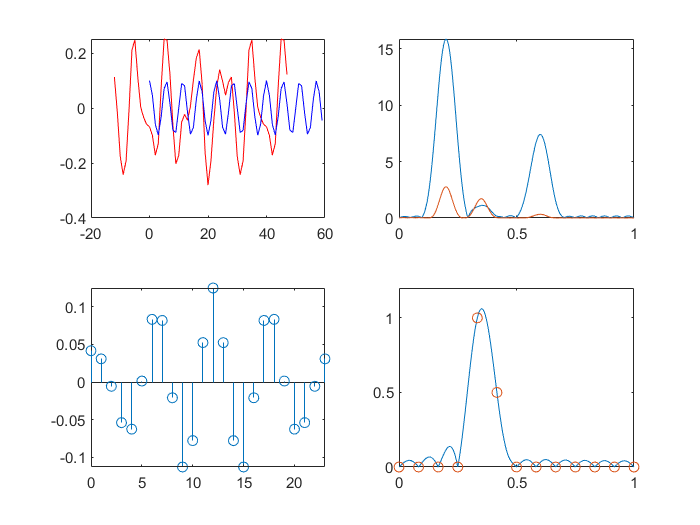

n1 = linspace(-Nf+1,N-1,N+Nf-1);
x1 = 1.5*cos(f1*pi*n1)+0.1*cos(f2*pi*n1)+0.7*cos(f3*pi*n1);
y1 = ifft(fft(x1).*fft(h,N+Nf-1));
y  = y1(Nf:N+Nf-1);
Yw = DTFT(y.*hamming(N)',n,w);
Hw = DTFT(h,k,w);
subplot(221);plot(n-Nf/2,real(y),'r',n,0.1*cos(f2*pi*n),'b');subplot(222);plot(w/pi,abs(Xw),w/pi,abs(Yw))
subplot(223);stem(k,real(h));subplot(224);plot(w/pi,abs(Hw),kf,abs(H),'o');axis([0 1 0 1.2])